# Christmas Dinner

N_old = 2;
N_adults = 8;
N_young = 20;

N = [ N_old, N_adults, N_young];

Infection and recovery rates

alpha_group = [ 0.5, 0.4, 0.3];
beta_group = [ 0.1, 0.2, 0.3 ];

M = [0.33, 0.33, 0.33;
    0.1, 0.8, 0.1;
    0.1, 0.1, 0.8];

Initial Condition

I0 = [0, 0, 2]; % 2 of the young are in infected
S0 = N - I0;
R0 = [0, 0, 0];

T = 30;
dt = 0.1;
time = 0:dt:T;

S = zeros(length(time), 3);
I = zeros(length(time), 3);
R = zeros(length(time), 3);

% Init first row
S(1, :) = S0;
I(1, :) = I0;
R(1, :) = R0;

Simulation

for t=2:length(time)
    dS = zeros(1, 3);
    dI = zeros(1, 3);
    dR = zeros(1, 3);

    for i = 1:length(N)
        infection = 0;
        for j = 1:length(N)
            effective_alpha = alpha_group(i) * M(i, j);
            infection = infection + effective_alpha * S(t-1, i)* I(t-1, j) / N(j);
        end
        dS(i) = - infection;
        dI(i) = infection - beta_group(i) * I(t-1, i);
        dR(i) = beta_group(i) * I(t-1, i);
    end

    S(t, :) = S(t-1, :) + dS * dt;
    I(t, :) = I(t-1, :) + dI * dt;
    R(t, :) = R(t-1, :) + dR * dt;
end

Plot

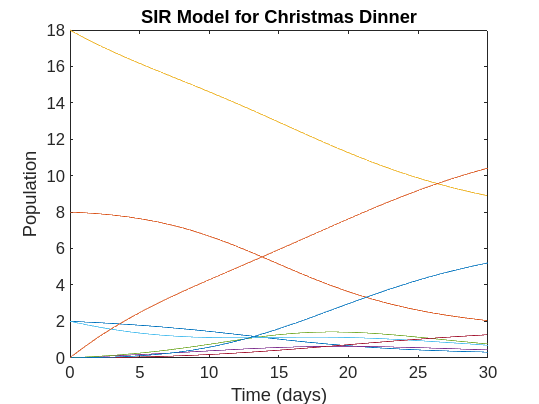

figure;
plot(time, S);
hold on;
plot(time, I);
plot(time, R);
xlabel('Time (days)');
ylabel('Population');
title('SIR Model for Christmas Dinner');

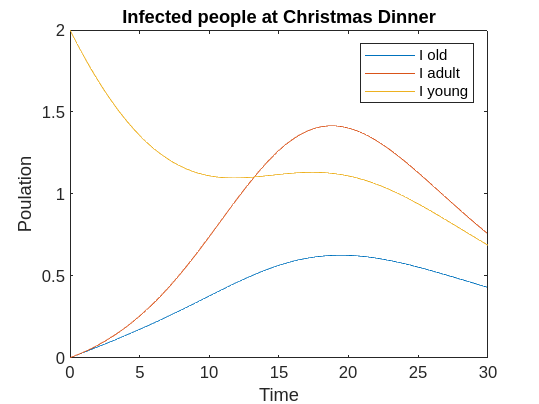


figure;
plot (time, I);
legend('I old', 'I adult', 'I young');
xlabel('Time');
ylabel('Poulation');
title('Infected people at Christmas Dinner');